# SELEX7620 Lab 2

Name:  Taewoo Kim, A01284763, and set T

Objective:  to simulate and measure a second order lowpass filter

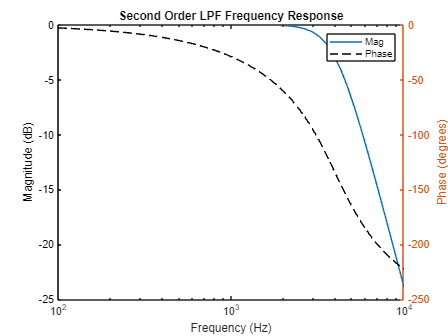

fc=4000;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s

%modify the code below to create the transfer function
%store transfer function in variable name H1 and H2
b = 1;
a = [1/wc^2 1/wc 1];
c = [1/wc 1];
H1 = tf(b,a);
H2 = tf(b,c);
H = H1*H2;

%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Calculate Component Values for PWM DAC Filter

## 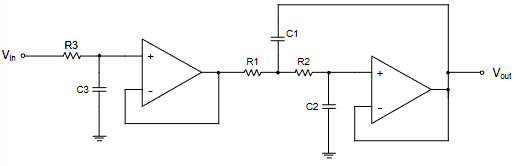

%Show your work for the steps below by inserting some documentation above or below this code block

%Specify the constraint for C2 / C1

%C1 = 4*C2; Which means C2/C1 = 0.25

%Set C1 and C2
C1 = 400*10^-9

C1 = 4.0000e-07

C2 = C1/4

C2 = 1.0000e-07

C3 = 100*10^-9

C3 = 1.0000e-07

%Calculate the values for R1 and R2
%R1 = ((C1/wc)+sqrt((C1/wc)^2 - 4*(C1*C2)* 1/(wc)^2))/(2*C1*C2)
%R2 = 1/(wc^2 * C1 * C2 * R1)
R1 = 200

R1 = 200

R2 = 200

R2 = 200

R3 = 390

R3 = 390

Steps to calculate the values for 2nd order low pass filter:

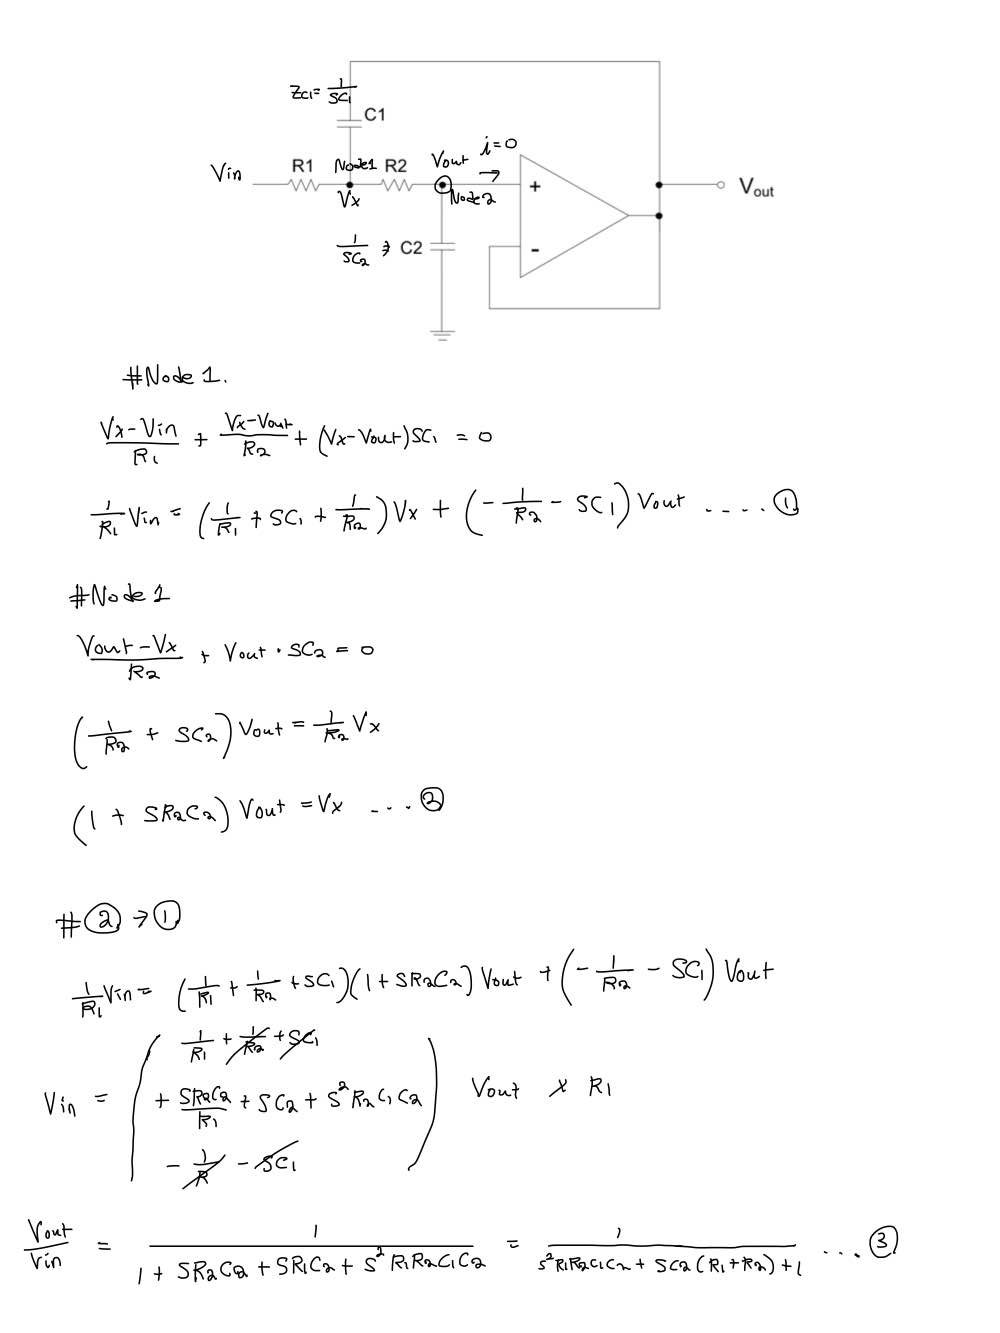

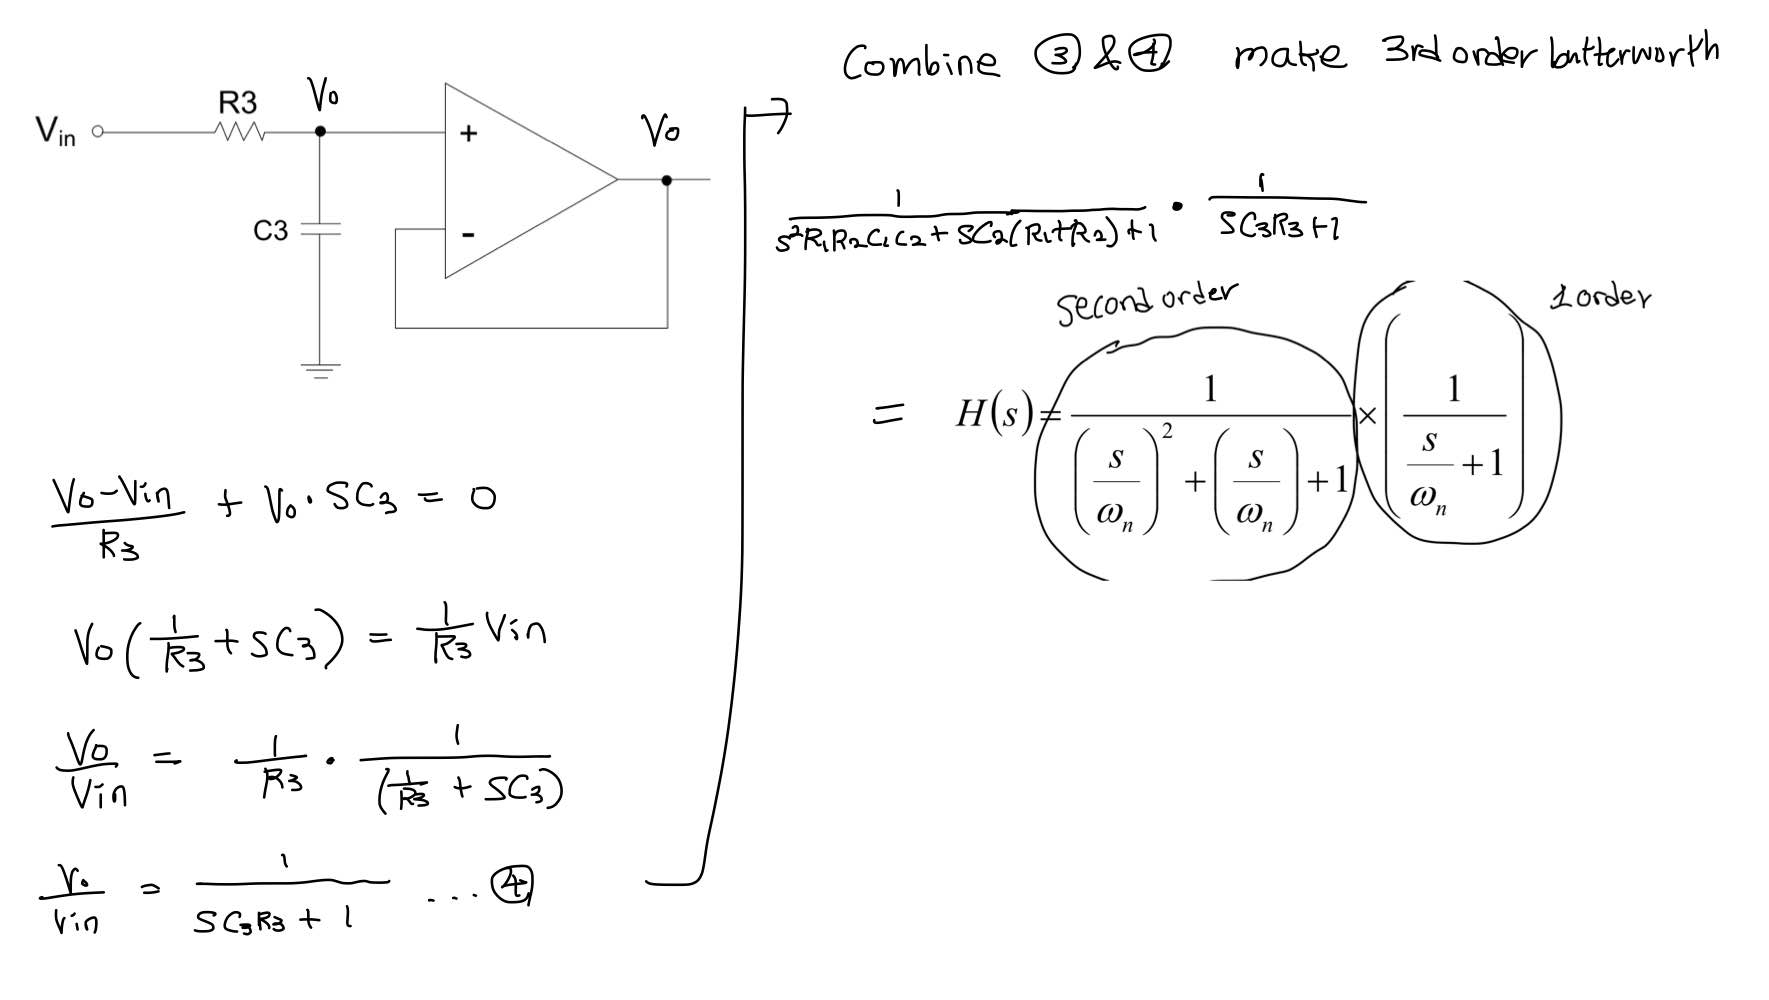

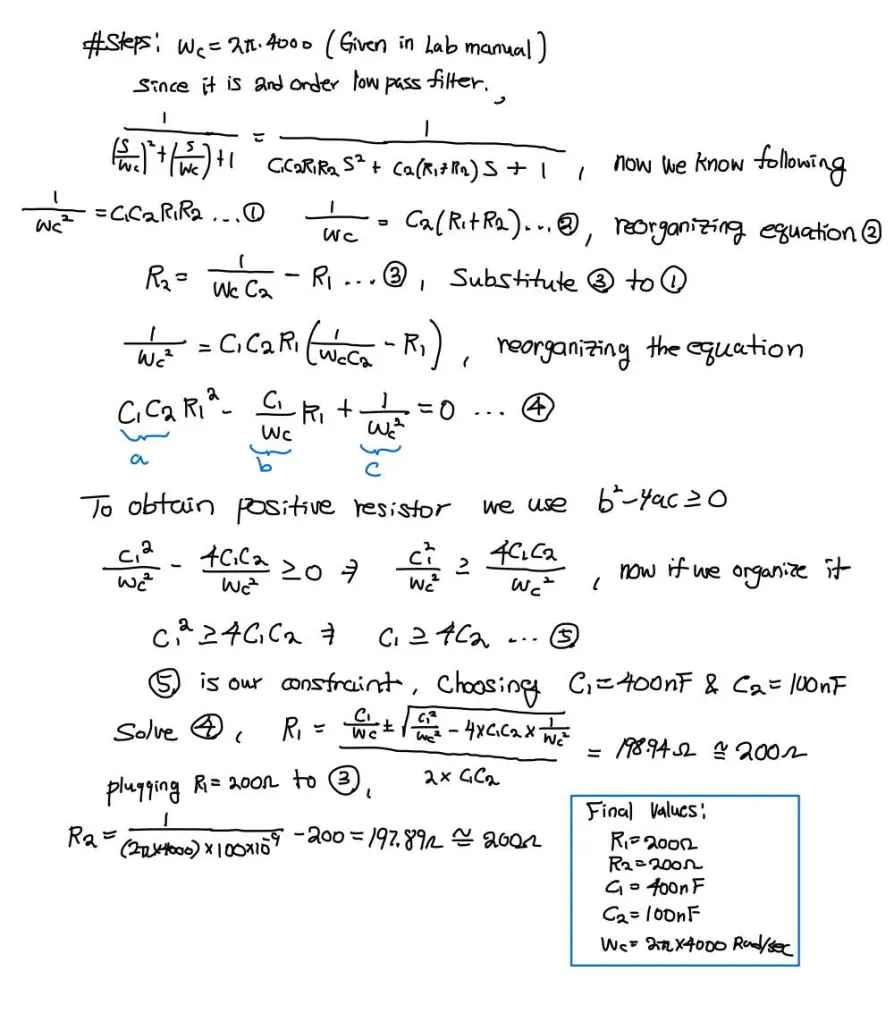

Steps for the extra 1st order low-pass filter:

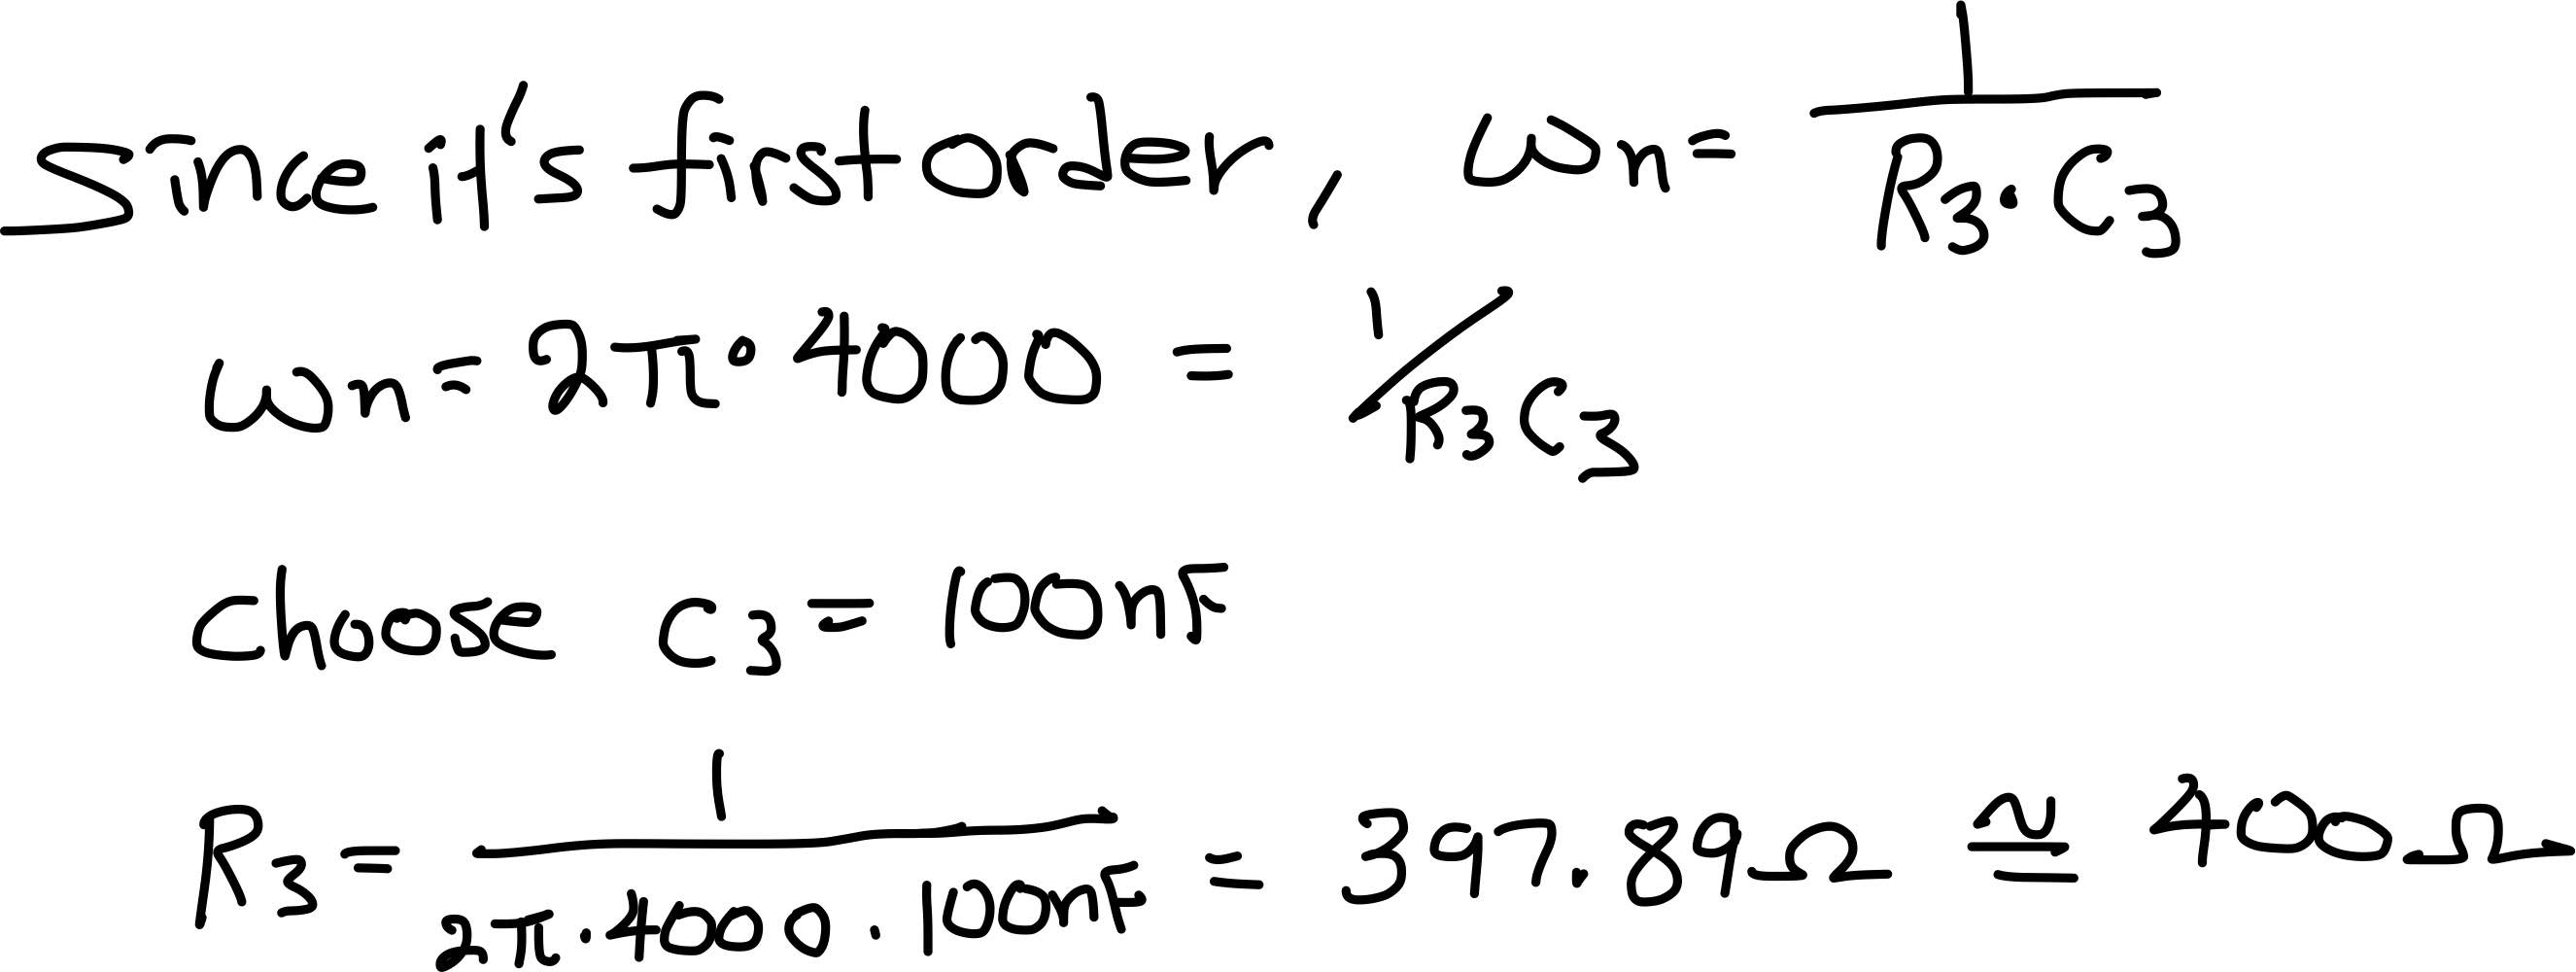

## LTSPICE Schematic

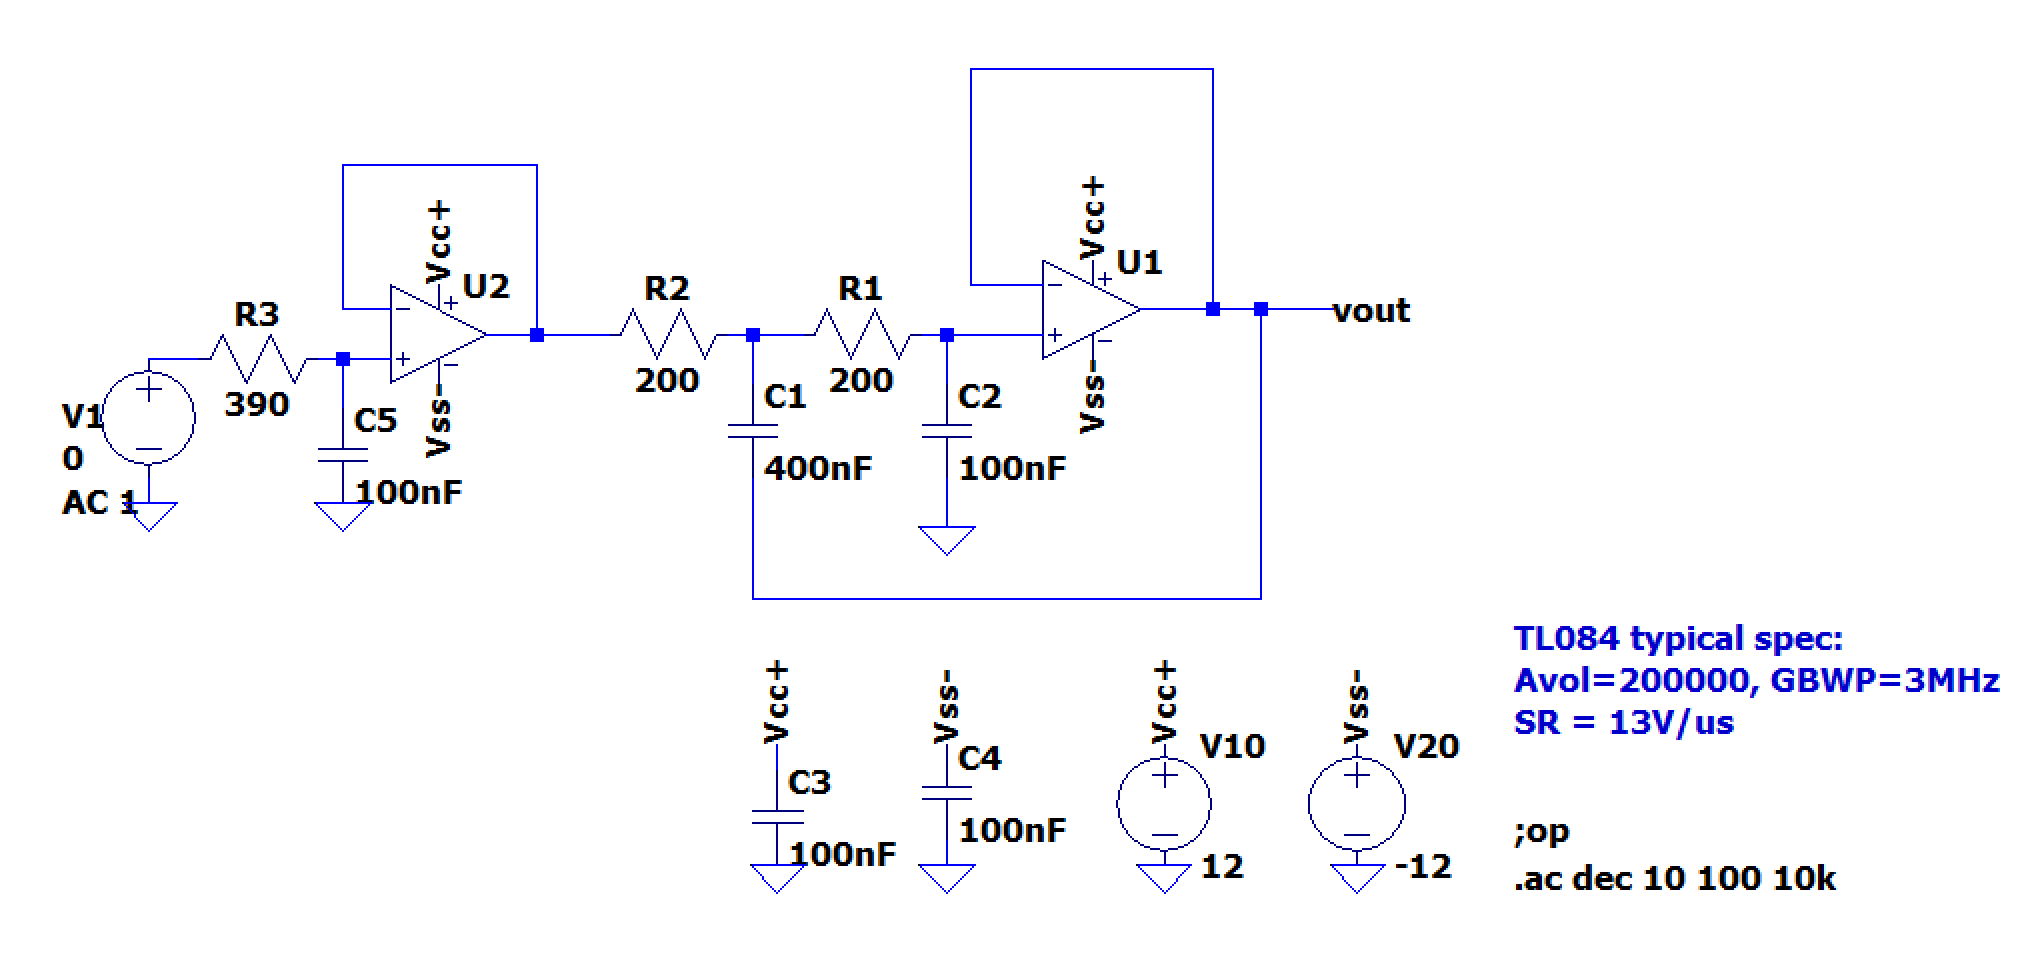

## LTSPICE Simulation Results

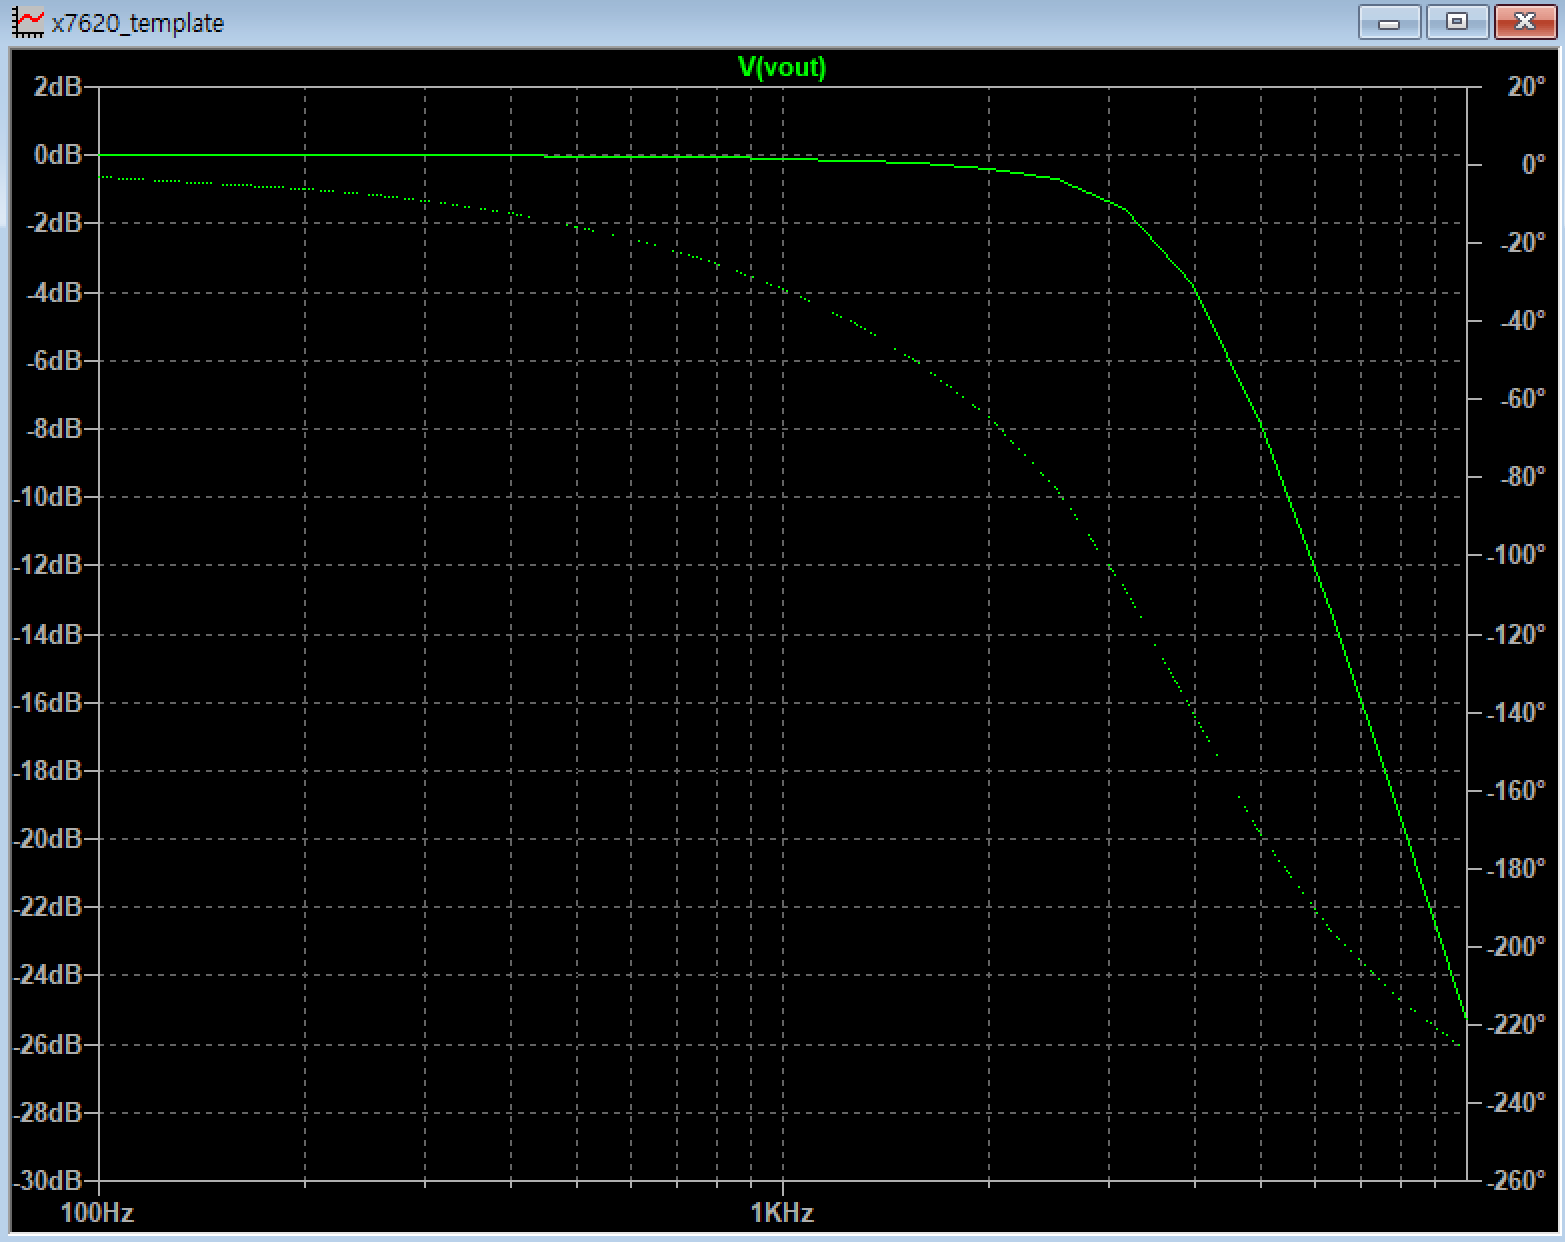

- Matlab plot and my ltspice simulation results match.

## **Dual supply measurements:**

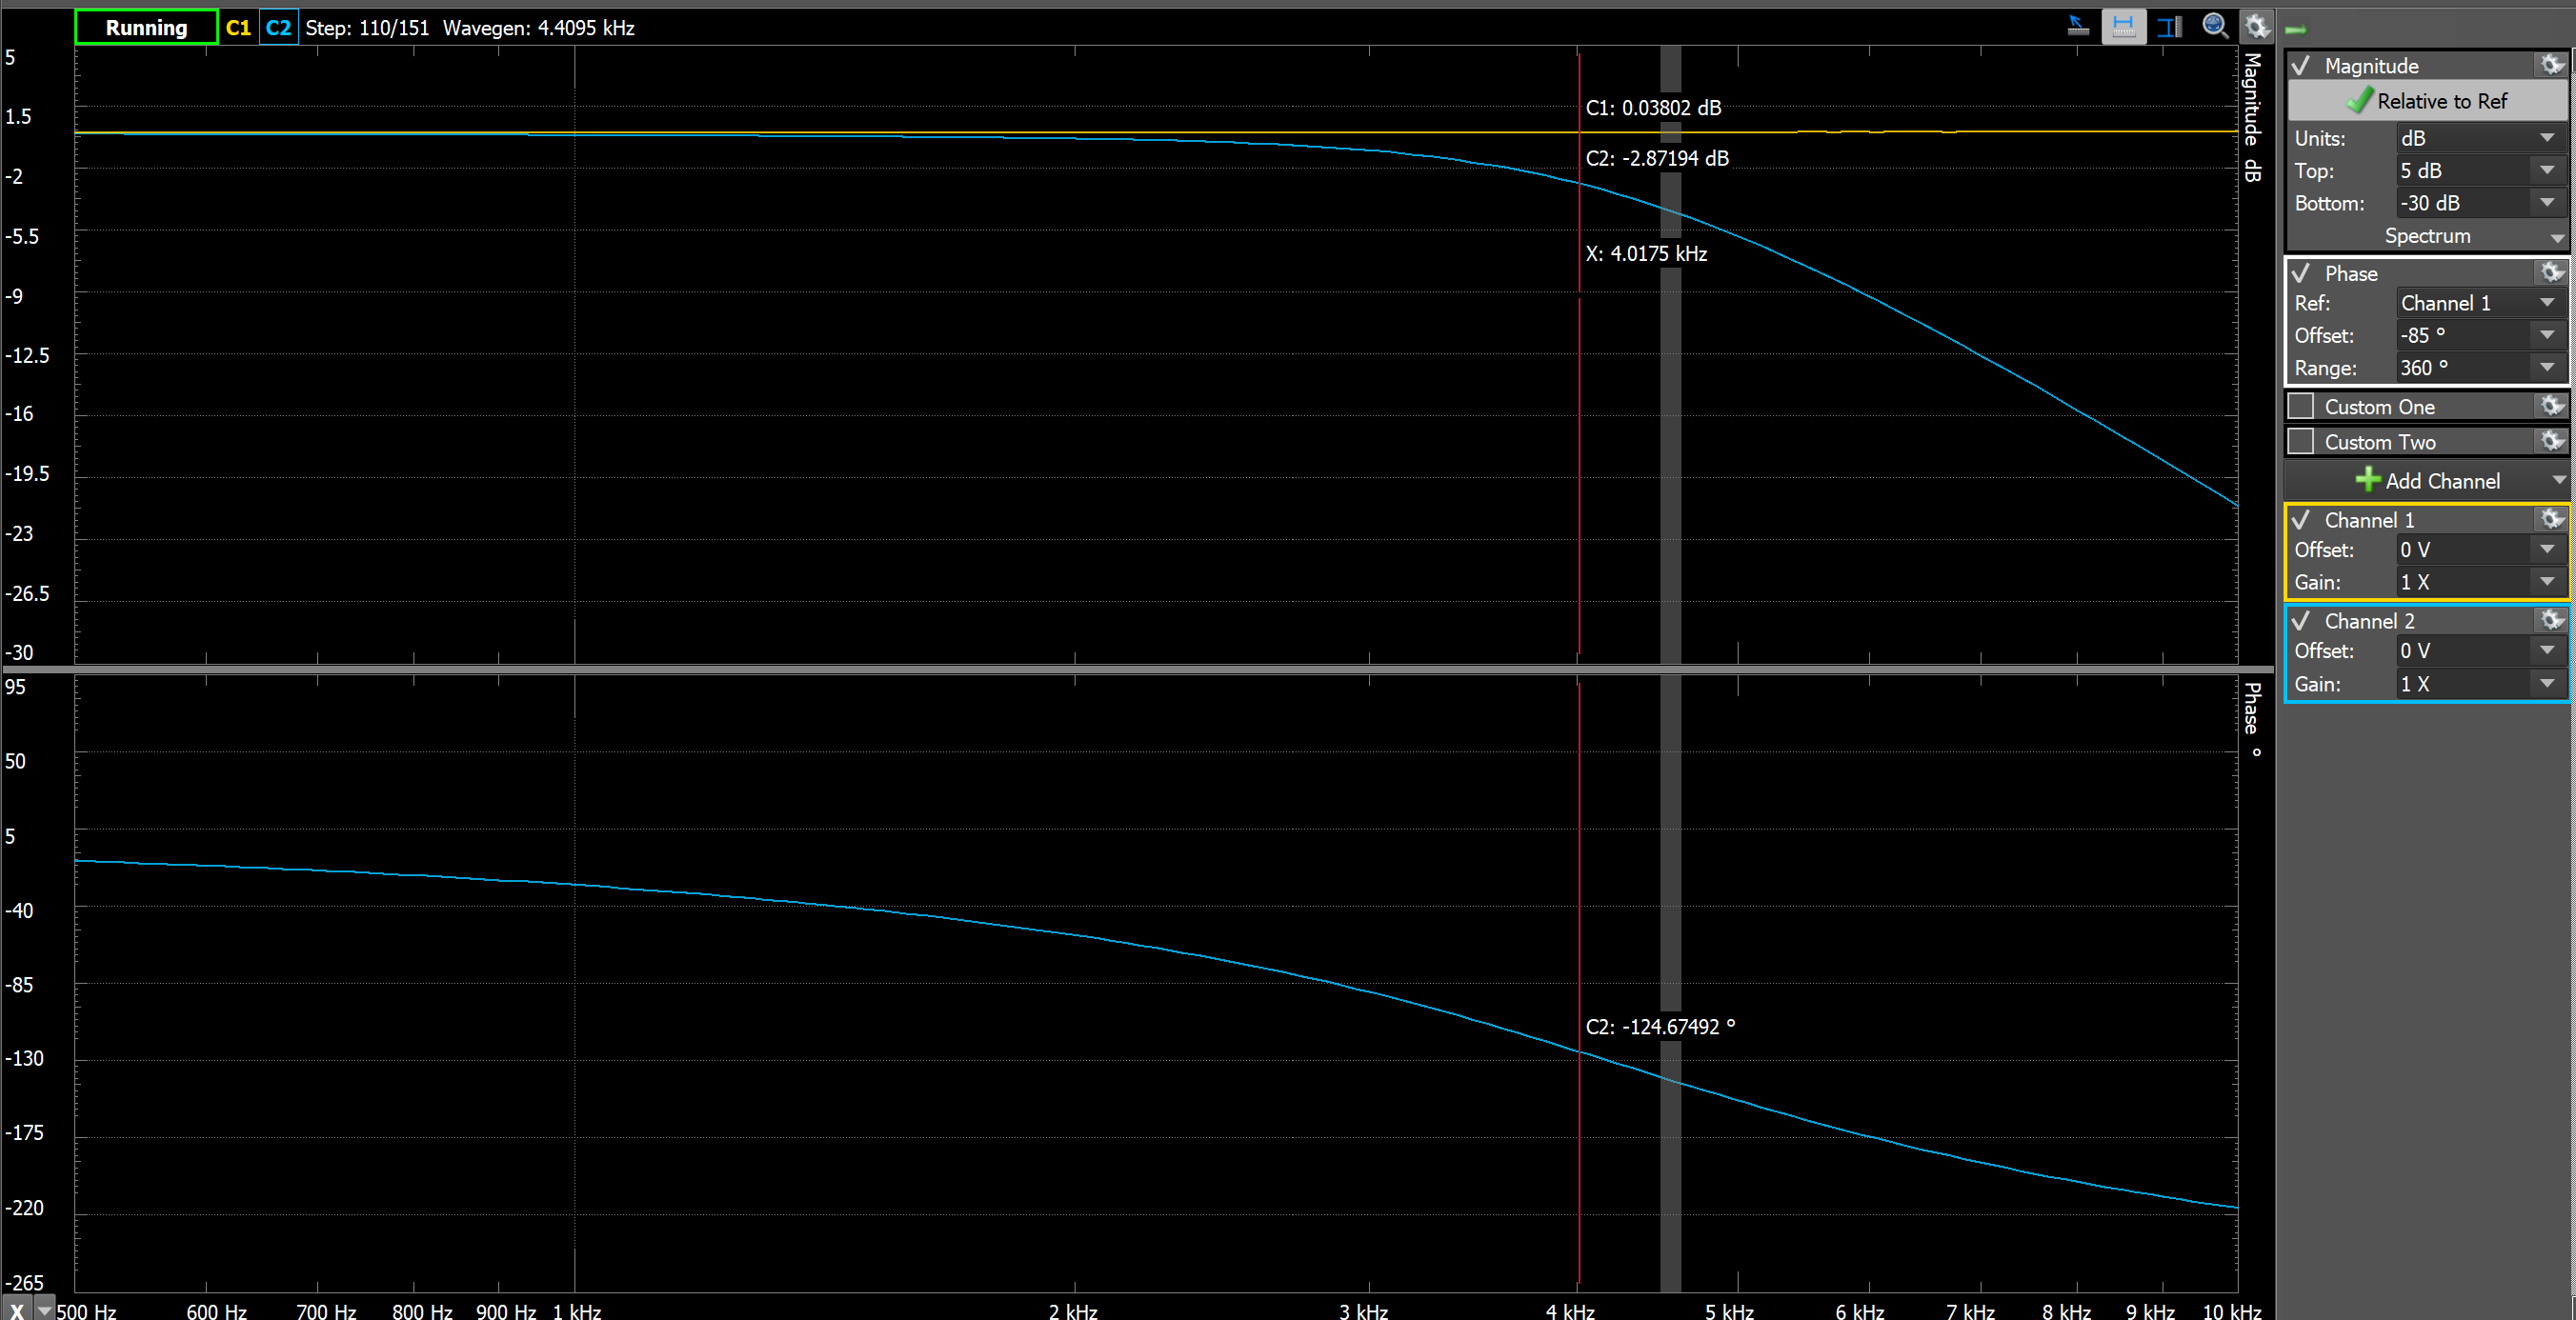

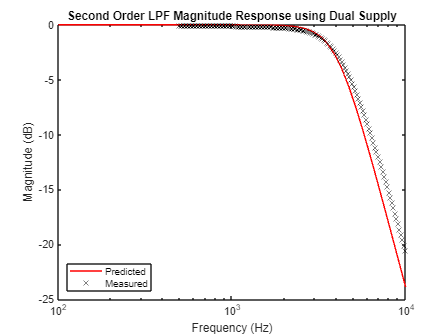

% Read table from the csv file
measured = readtable('Dual_supply.csv', 'VariableNamingRule', 'preserve');

% Extract all the values
meas_freq = measured.("Frequency (Hz)");
meas_mag_dB = measured.("Channel 2 Magnitude (dB)");
meas_phase = measured.("Channel 2 Phase (deg)");

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Magnitude Response using Dual Supply')
legend('Predicted', 'Measured', 'Location', 'southwest');

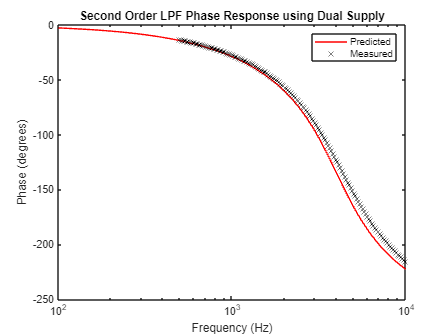


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Second Order LPF Phase Response using Dual Supply')
legend('Predicted', 'Measured')

## Single Supply Measurements

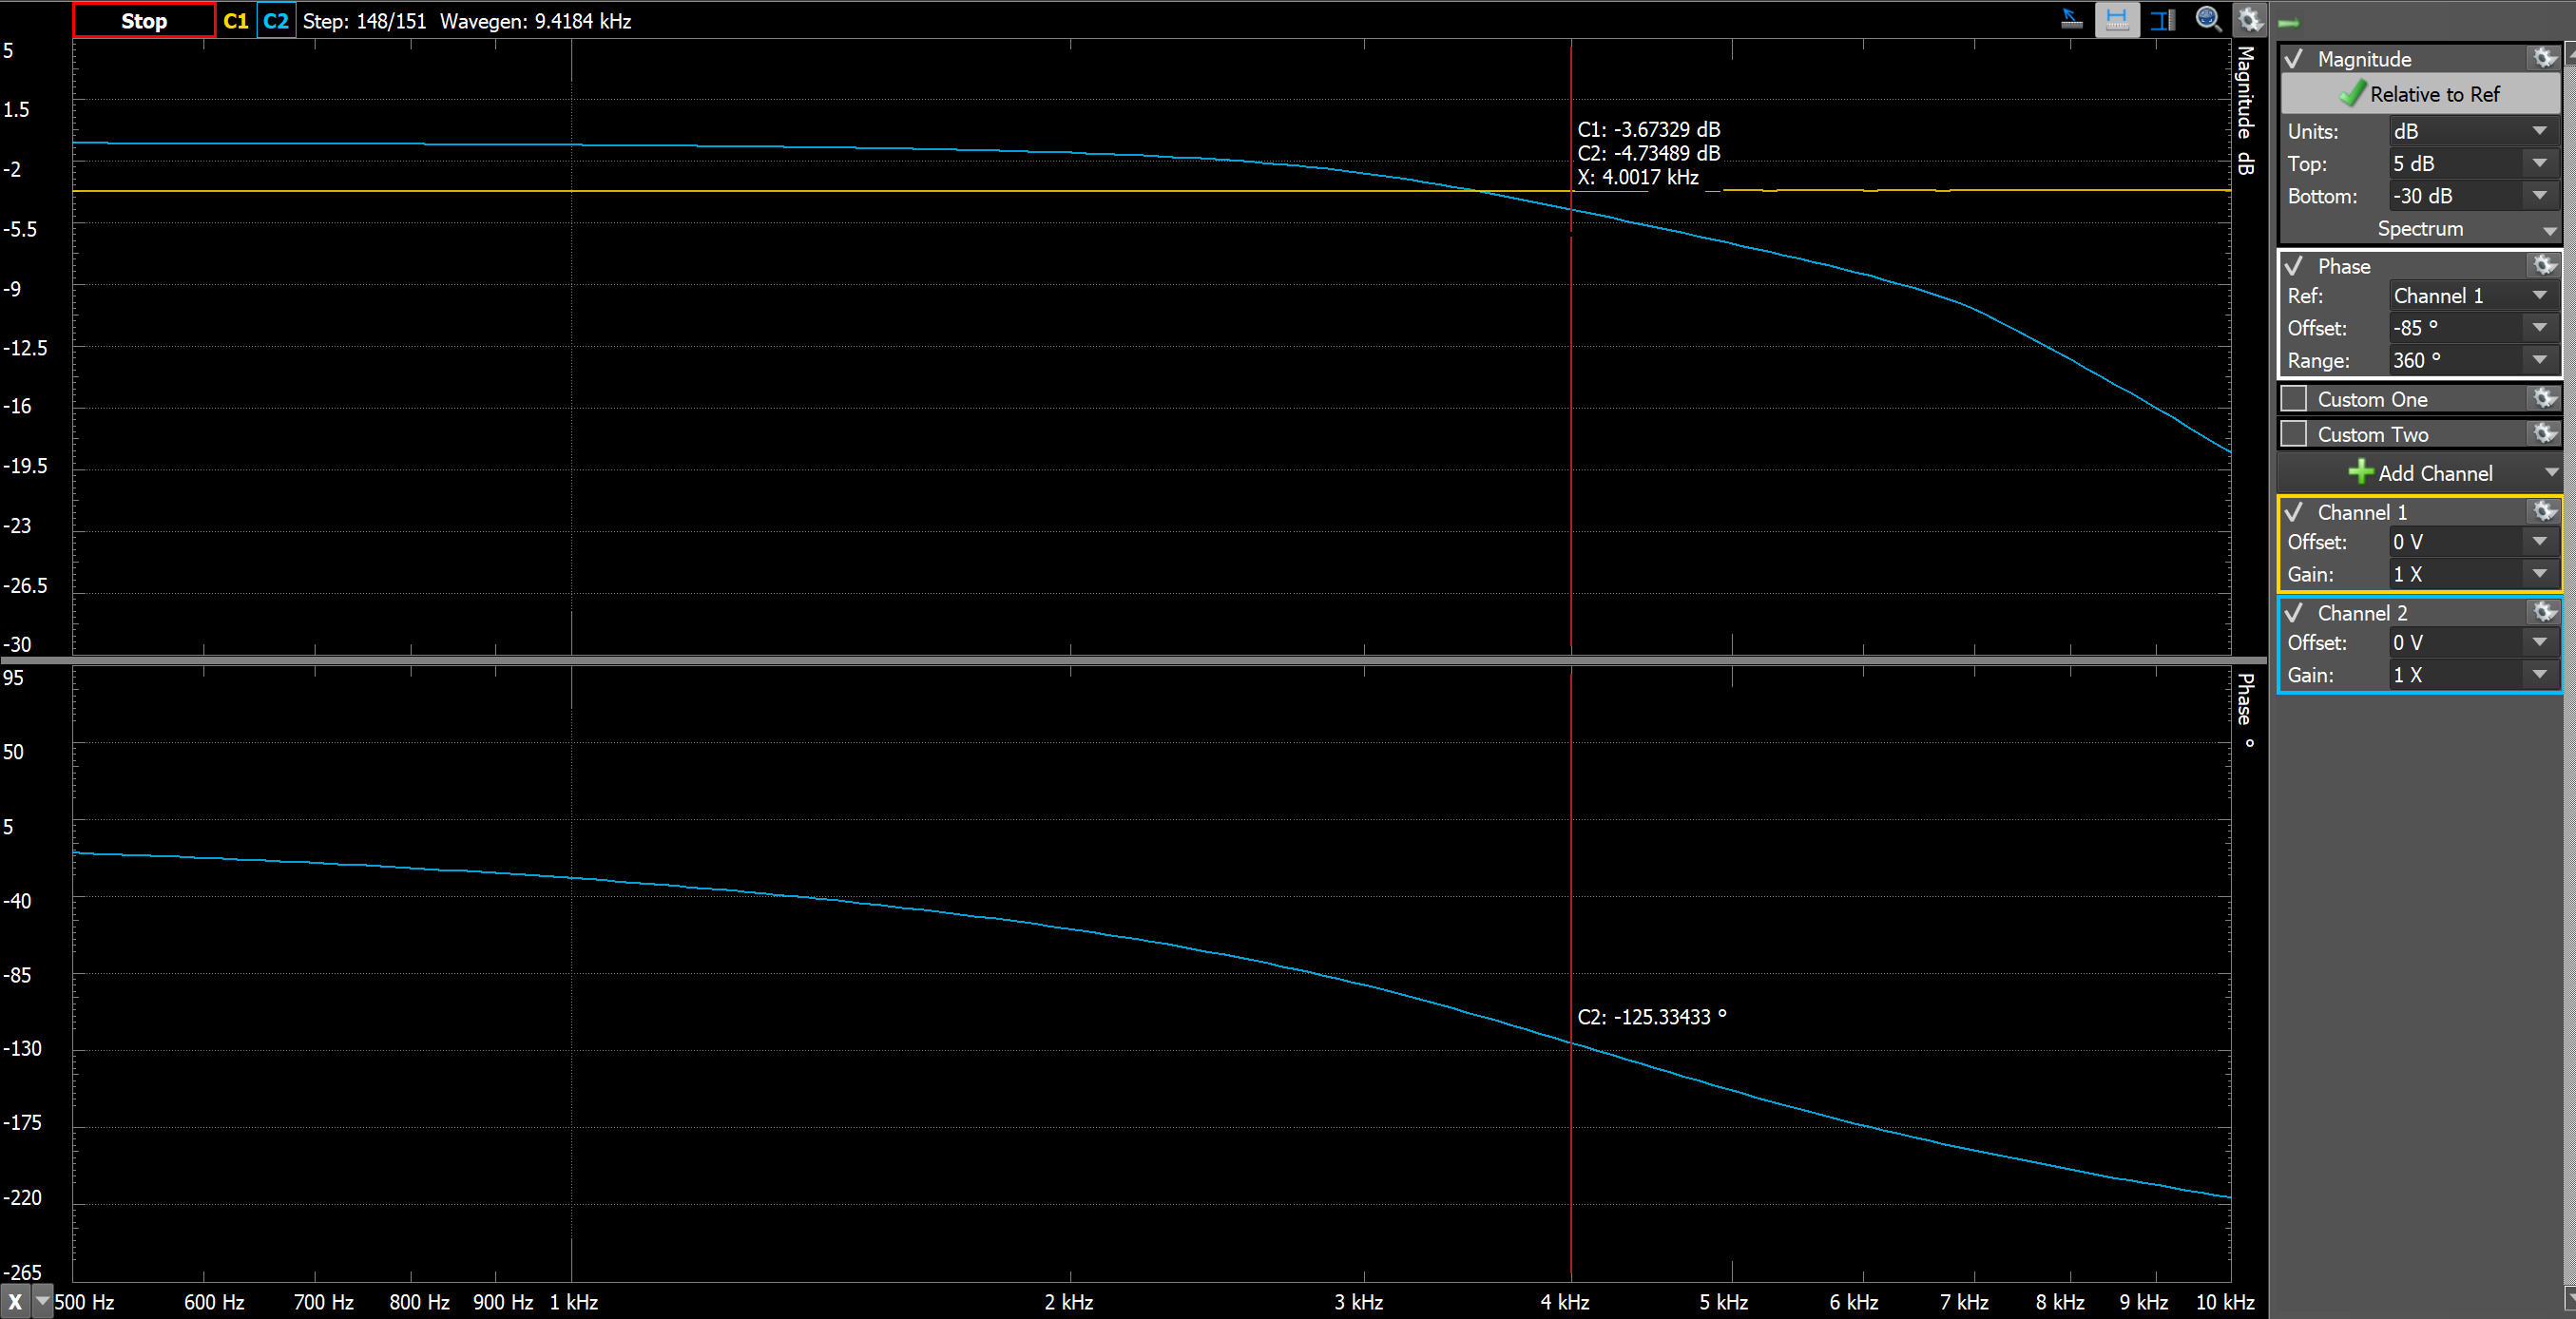

Q: Measure the frequency response again, but note that you will need to apply a DC offset to the input signal; explain why this is required for proper operation of the filter.

A: When using the op-amp with a single supply and connecting the negative pin to the ground, the input and output signals are now limited from 0V to 5V This creates a restriction because op-amp can't handle the signals that go below ground as there is no negative voltage connected.

To handle this issue, we provide a dc offset (mid point from 5 V which is 2.5V), without a dc offset an AC input signal would have negative portions (sine wave centered at 0V). These negative voltage will be clipped because op-amp can not handle voltages below 0V. Therefore, we need to provide the dc offset to resolve this issue. 

2.5V is selected since it is the mid point from 0 V to 5V, which means now the sine wave of the input will range from 2V to 3V (If sine wave 1Vpp is selected) which is in the range of 0V to 5V.

Record your measured data here and compare it against the theoretical results

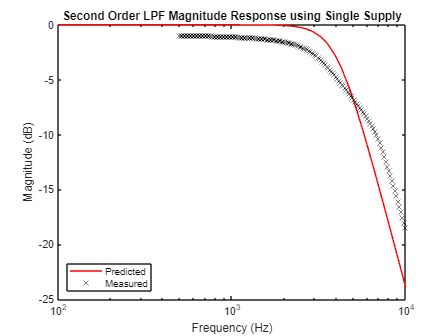

measured = readtable('Single_supply.csv', 'VariableNamingRule', 'preserve');

% Extract all the values
meas_freq = measured.("Frequency (Hz)");
meas_mag_dB = measured.("Channel 2 Magnitude (dB)");
meas_phase = measured.("Channel 2 Phase (deg)");


figure(4)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Magnitude Response using Single Supply')
legend('Predicted', 'Measured', 'Location', 'southwest');

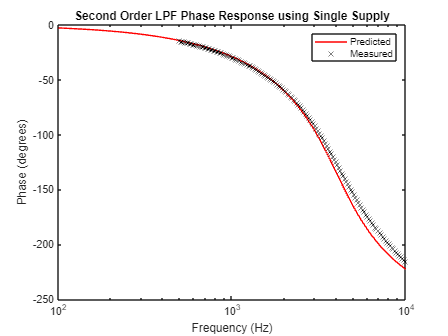


figure(5)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Second Order LPF Phase Response using Single Supply')
legend('Predicted', 'Measured')